% clear
% 
% % Read img file
% img = imread("../db/DB1/db1_07.jpg");
% 
% % Normalize colors
% img_gw = gray_world(img);
% 
% % Create facemask 
% face_mask = facemask(img_gw);
% imshow(face_mask)
% 
% %Find eyes and a mouth
% eyes = eyemap(img_gw);
% eye_mask = eyemask((eyes),face_mask);
% %eye_mask = hybrid(img_gw);
% imshow(eye_mask)
% 
% mouth = mouth_map(img_gw);
% mouth_mask = mouthmask(mouth) & face_mask;
% imshow(mouth_mask)
% 
% [x,y] = mouth_index(mouth_mask)
% 
% [indexX,indexY] = eye_index(eye_mask)
% % Replace with actual coordinates
% mouth_center = [x, y]; 
% [eye1 , eye2, angle] = findEyePair(indexX,indexY,mouth_center)
% 
% % Visualize the original image with detected eyes and mouth
% figure;
% imshow(img);
% hold on;
% viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
% plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')

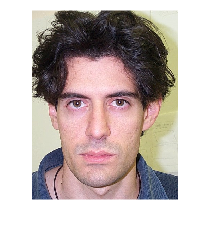

clear
%Problem with: 7,14
% Read img file
img = imread("../db/DB1/db1_14.jpg");
imshow(img)

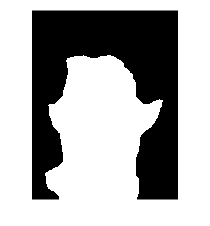


% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

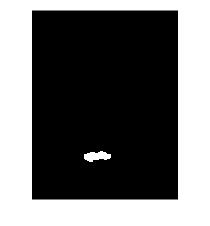


%Find eyes and a mouth
eyes = eyemap(img_gw);
%eye_mask = eyemask((eyes),face_mask);

%imshow(eye_mask)

mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)


[x,y] = mouth_index(mouth_mask)

x = 184.2135

y = 414.1828

Index in position 1 exceeds array bounds.

Error in findEyePair (line 90)
    plot([selected_eyes(1, 1), selected_eyes(2, 1)], [selected_eyes(1, 2), selected_eyes(2, 2)], 'LineWidth', 2, 'Color', 'r');

Error in iterativeEyeFinder (line 5)
    [eye1 , eye2] = findEyePair(indexX,indexY,mouth_center,img);


%[indexX,indexY] = eye_index(eye_mask)
% eye_centers = cat(length(indexX),x,y);
%----------------------------------------%
% Calculate the center of the mouth (you might need to adjust this based on your specific case)
mouth_center = [x, y]; % replace with actual coordinates
[eye1,eye2]= iterativeEyeFinder(eyes,face_mask,mouth_center,img)

figure;
imshow(img);
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')